# Error Types, P-Values, False-Positives, and Power Analysis

## Exercise 1

Updated after review of answer key

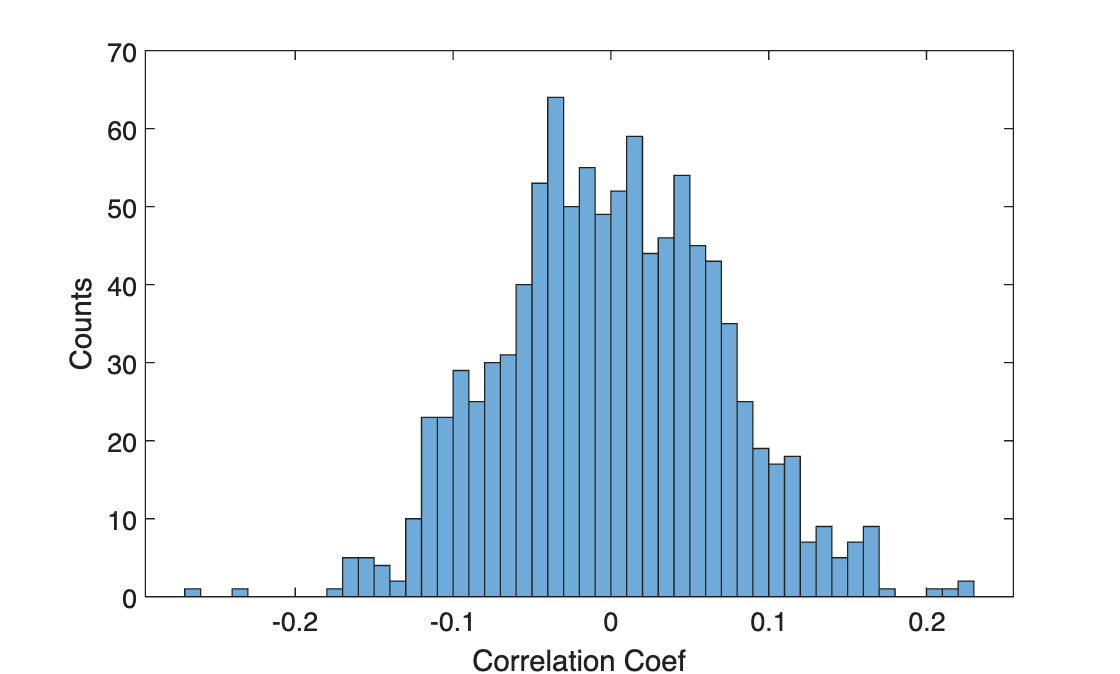

% Start by generating the data itself. Assume LC spike counts are Poisson
% distributed w/ rate of 1Hz and pupils are Gaussian (already been z-scored) 
% NOT using a pdf, generating the actual data points using rnd
trials = 200; 
experiments = 1000; 
spikeRates = poissrnd(1, trials, experiments);
pupils = normrnd(0, 1, trials, experiments);

% Create a holder and then compute correlation coefficients across all
% trials within each of the experiments
corrs = ones(1, experiments);
for i = 1:experiments
    corrs(i) = corr(spikeRates(:,i), pupils(:,i), 'type','Spearman');
end

% Display histgram of simulated null distribution
histogram(corrs, 50);
xlabel('Correlation Coef')
ylabel('Counts')

disp([mean(corrs) std(corrs)])

    0.0006    0.0697



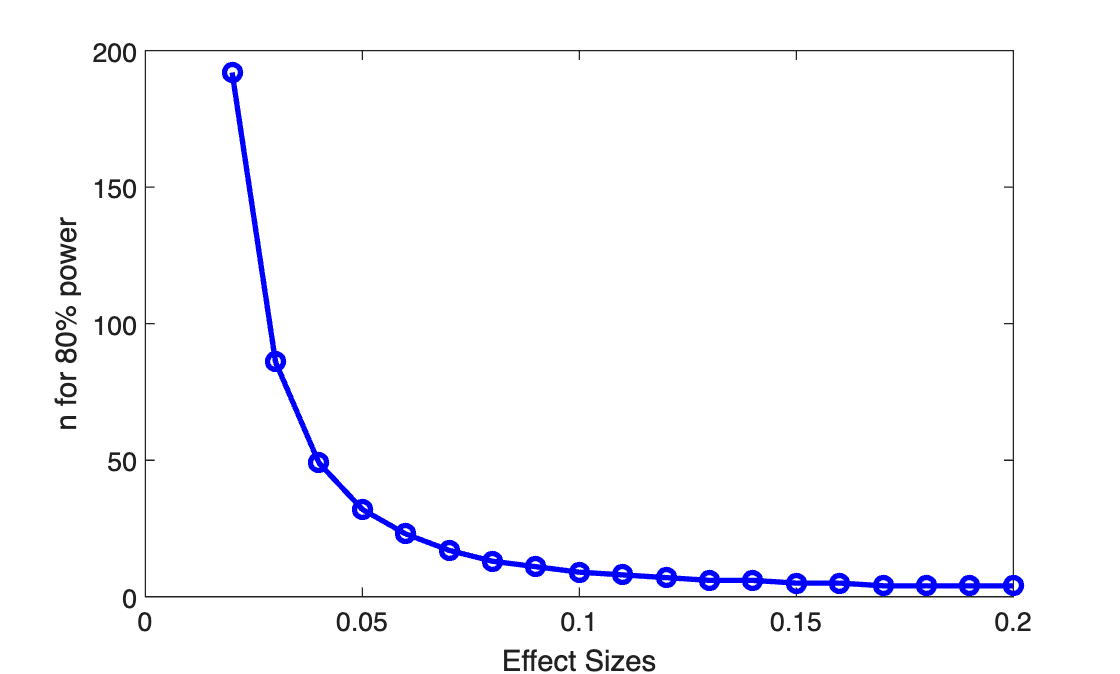


% Perform Power analysis using test type, mean and sd, effect size, and
% power. These are the inputs to sampsizepwer function 
% NOTE: The effect sizes are just the mean corr coeffs needed for a
% positive effect (reject the null) 
testType = 't2';
p0 = [0 std(corrs)];
effectSizes = (0.02:0.01:0.2)';
numEffectSizes = length(effectSizes);
power = 0.8; 

% Loop through each of the effect sizes and compute power
ns = zeros(numEffectSizes, 1);
for j = 1:numEffectSizes
    ns(j) = sampsizepwr(testType, p0, effectSizes(j), power);
end

% Plot the results. Takeaway: Smaller effect sizes (i.e. true value is
% distinct but still very close to null) require much larger N to prove
% distinction than larger effect sizes
plot(effectSizes, ns, 'bo-', 'LineWidth', 2)
xlabel('Effect Sizes')
ylabel('n for 80% power')